%% Ma quanto so' belli sti dati oh
clc
clear all
close all

table=readtable("forzanapoli-20230613124635.csv");

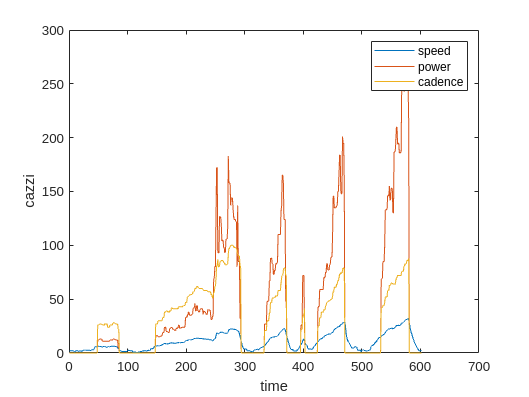


table= table(:,2:end);

time=1:1:size(table,1);


speed = table2array(table(:,"Speed_km_h_"));
power = table2array(table(:,"Power_watt_"));
cadence = table2array(table(:,"Cadence"));

plot(time,speed,time, power,time,cadence);

legend("speed","power","cadence");
ylabel("cazzi");
xlabel("time");

test = speed(579:597,1);
x = size(test,1);
xx = 1:x;


pp = polyfit(xx,test,3);
p = polyval(pp,xx)

p =    32.5761   29.7750   27.1349   24.6507   22.3172   20.1294   18.0821   16.1702   14.3885   12.7319   11.1953    9.7736    8.4615    7.2540    6.1460    5.1323    4.2078    3.3674    2.6058


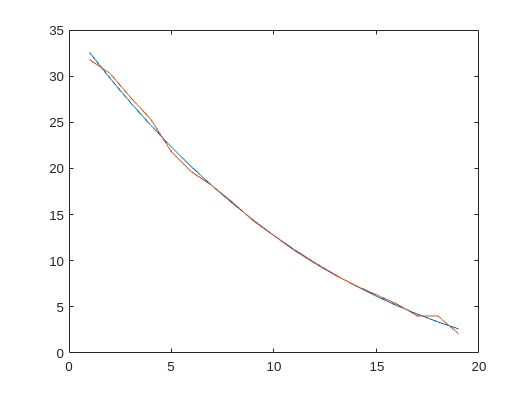


plot(xx,p);
hold on
plot(xx,test);